## Segmentation of oranges in RGB

Load and display images.

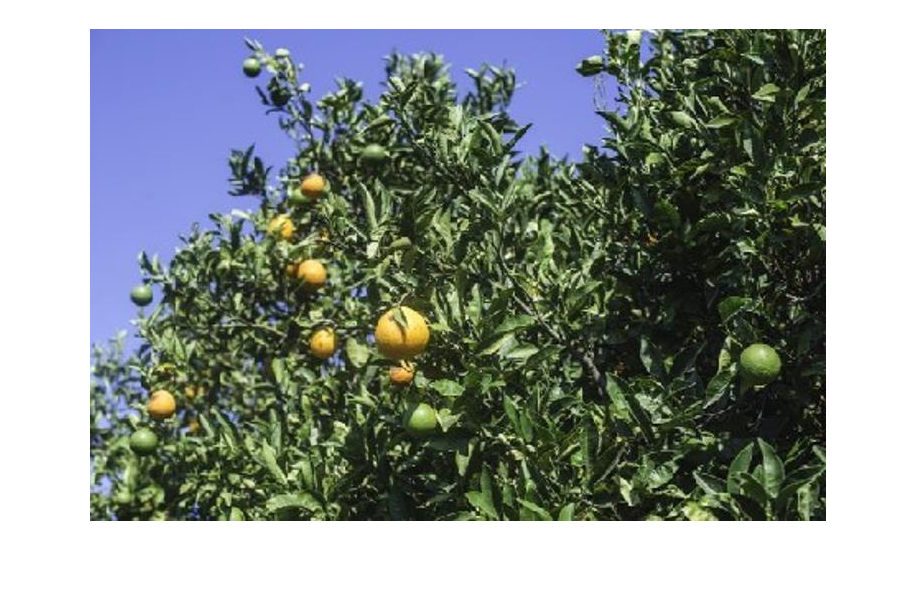

oranges = imread("./images/orangeTree.jpg");
imshow(oranges)

% orangeColor = drawpolygon;
% BW = createMask(orangeColor);

BW = logical(readmatrix("./images/orangeMask.csv", OutputType="uint8"));
oranges = im2double(oranges);
[red,green,blue] = imsplit(oranges);

Extract intensities from the sample color.

rROI = red(BW);
gROI = green(BW);
bROI = blue(BW);

Calculate the average of the red, green, and blue intensities in the sample color.

meanROI_RGB = mean([rROI gROI bROI]);

Calculate the distance of each pixel from the sample color.  Since each color plane measures some type of chrominance, you need all three channels.

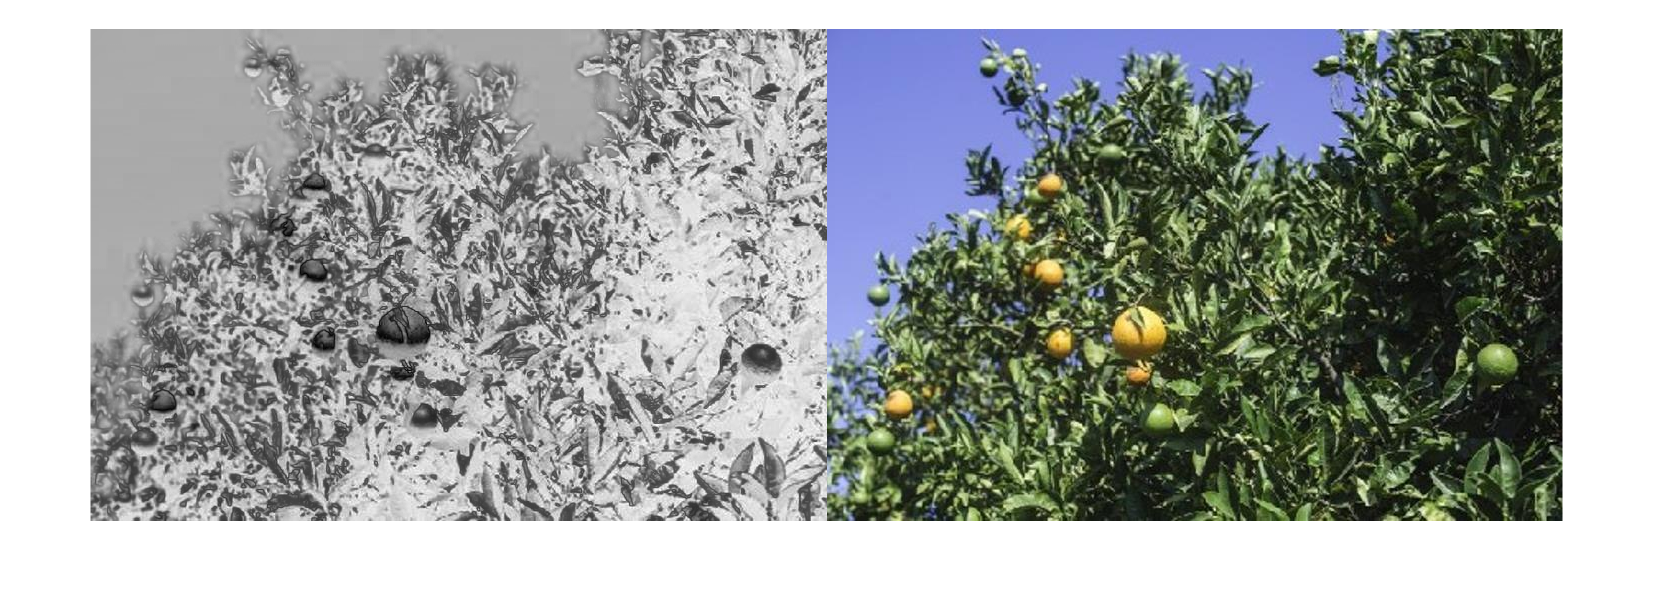

distRGB = sqrt((red - meanROI_RGB(1)).^2 + (green - meanROI_RGB(2)).^2 + (blue - meanROI_RGB(3)).^2);
imshowpair(distRGB, oranges, "montage") 

Threshold the distance matrix and display the results.

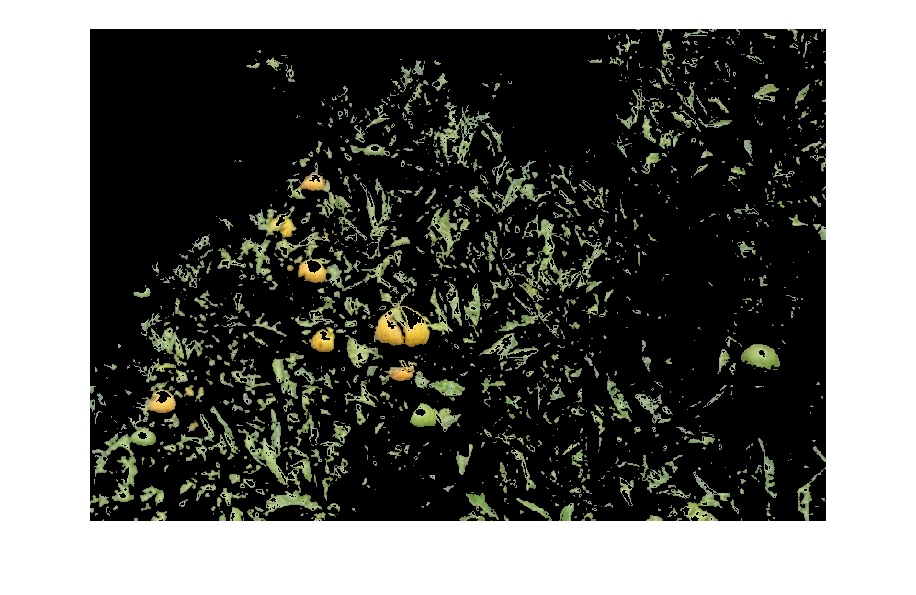

maskRGB = distRGB < .4;
rgbOranges = imoverlay(oranges, ~maskRGB, "black");%(oranges,mask,"montage") 
imshow(rgbOranges)